% Cargar imagen
img = imread("CUADRO.jpg");
img_gray = rgb2gray(img);

% Mostrar la imagen original
figure;
imshow(img_gray), title('Imagen Original');

% Seleccionar 4 puntos en la imagen original
disp('Selecciona 4 puntos de las esquinas de la hoja en el orden:');

Selecciona 4 puntos de las esquinas de la hoja en el orden:


disp('1. Esquina superior izquierda'); disp('2. Esquina superior derecha');

1. Esquina superior izquierda
2. Esquina superior derecha


disp('3. Esquina inferior derecha'); disp('4. Esquina inferior izquierda');

3. Esquina inferior derecha
4. Esquina inferior izquierda


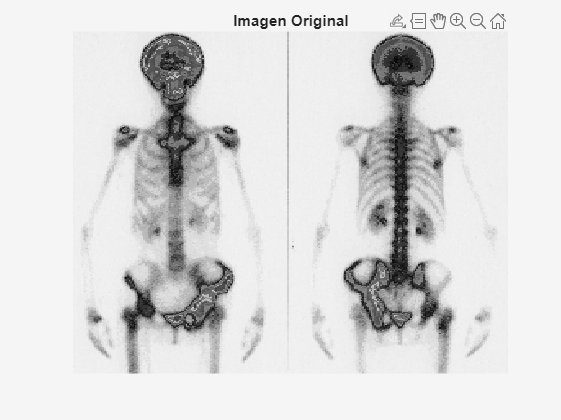

[x, y] = ginput(4);

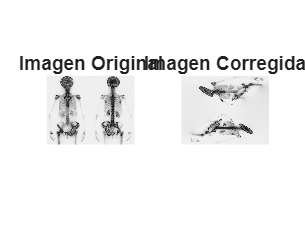


% Coordenadas seleccionadas
x1 = x(1); y1 = y(1);
x2 = x(2); y2 = y(2);
x3 = x(3); y3 = y(3);
x4 = x(4); y4 = y(4);

[alto, ancho] = size(img_gray); 

% Coordenadas deseadas
i1 = 0; j1 = 0;  % Esquina superior izquierda
i2 = ancho; j2 = 0;  % Esquina superior derecha
i3 = ancho; j3 = alto;  % Esquina inferior derecha
i4 = 0; j4 = alto;  % Esquina inferior izquierda

% Definir las incógnitas
syms a1 a2 a3 a4 b1 b2 b3 b4

% Definir las ecuaciones
eq1 = a1 * x1 + a2 * y1 + a3 * x1 * y1 + a4 == i1;
eq2 = b1 * x1 + b2 * y1 + b3 * x1 * y1 + b4 == j1;

eq3 = a1 * x2 + a2 * y2 + a3 * x2 * y2 + a4 == i2;
eq4 = b1 * x2 + b2 * y2 + b3 * x2 * y2 + b4 == j2;

eq5 = a1 * x3 + a2 * y3 + a3 * x3 * y3 + a4 == i3;
eq6 = b1 * x3 + b2 * y3 + b3 * x3 * y3 + b4 == j3;

eq7 = a1 * x4 + a2 * y4 + a3 * x4 * y4 + a4 == i4;
eq8 = b1 * x4 + b2 * y4 + b3 * x4 * y4 + b4 == j4;

% Resolver sistema de ecuaciones
solx = vpasolve([eq1, eq3, eq5, eq7], [a1, a2, a3, a4]);
soly = vpasolve([eq2, eq4, eq6, eq8], [b1, b2, b3, b4]);

% Sustituir soluciones simbólicas a valores numéricos
a1 = double(solx.a1); a2 = double(solx.a2); a3 = double(solx.a3); a4 = double(solx.a4);
b1 = double(soly.b1); b2 = double(soly.b2); b3 = double(soly.b3); b4 = double(soly.b4);

% Crear la img corregida
img_transformed = NaN(alto, ancho);

% Recorrer todos los píxeles de la imagen original y hacer mapeo
for x = 1:ancho
    for y = 1:alto
        % Coordenadas img corregida
        i = a1 * x + a2 * y + a3 * x * y + a4;
        j = b1 * x + b2 * y + b3 * x * y + b4;
        
        % Coordenadas dentro de los límites 
        if i >= 1 && i <= ancho && j >= 1 && j <= alto
            img_transformed(round(j), round(i)) = img_gray(y, x);
        end
    end
end

% Rellenar pixeles vacíos
mask = isnan(img_transformed); 
img_transformed_filled = img_transformed;
img_transformed_filled(mask) = 0;

% Filtro para pixeles en 0
img_transformed_filled = regionfill(img_transformed_filled, mask);

img_transformed_filled = uint8(img_transformed_filled);

figure;
subplot(1, 2, 1), imshow(img_gray), title('Imagen Original');
subplot(1, 2, 2), imshow(img_transformed_filled), title('Imagen Corregida');